# Magnetic field simulations

calculates the mutual inductance interaction between a transmitting and receiving coil

- mutual inductance between the coils

- voltage and current induced in the receiving coil by the transmitting coil

- change in voltage in transmitting coil capacitor induced by the receiving coil

clear all;

close all;

## CONSTANTS

## Coil physical characteristics

TX_D = 8e-2;      % coil diameter [m]
RX_D = 2e-2;
TX_NT = 20;       % # turns / layer
TX_NL = 6;
RX_NT = 20;       % # layers
RX_NL = 3;
TX_AWG = 26;      % wire gauge [awg]
RX_AWG = 26;

TX_C = 117e-9;    % capacitance [F]
RX_C = 3.2e-6;

## Simulation parameters

% driving AC frequency [Hz]
% f = 1e4;
f = linspace(9e3, 11e3, 100);  % sweep
omega = 2*pi*f;

% driving voltage [V]
TX_V = 5;

% receiver coil location [m] & orientation [unit vector]
% sweep location
% z = linspace(0,15,7); RX_LOC = [ zeros(length(z),2), z'] * 1e-2;
RX_LOC = [0,0,13.5] * 1e-2;

% sweep orientation
theta = linspace(0, 2*pi, 360);
RX_U = [zeros(size(theta));
        sin(theta);
        cos(theta)];

## Calculated constants

% total length of wire [m]
TX_l = TX_D*pi * TX_NT*TX_NL;
RX_l = RX_D*pi * RX_NT*RX_NL;

% cross-sectional area [m^2]
TX_A = pi * (TX_D/2)^2;
RX_A = pi * (RX_D/2)^2;

% inductance, resistance, axial length of coil [H, Ohms, mm]
[TX_L, TX_R, TX_a] = Lcalc(TX_AWG, TX_D*1000, TX_NT, TX_NL, mean(f));
[RX_L, RX_R, RX_a] = Lcalc(RX_AWG, RX_D*1000, RX_NT, RX_NL, mean(f));

% resonant frequency of each coil [Hz]
TX_resf = 1 / sqrt(TX_L * TX_C) / (2*pi)

TX_resf = 1.0087e+04

RX_resf = 1 / sqrt(RX_L * RX_C) / (2*pi)

RX_resf = 1.0032e+04

## Magnetic field

% magnetic field vector xyz [T]
B = Bfield(TX_D, TX_NT*TX_NL, RX_LOC(:,1), RX_LOC(:,2), RX_LOC(:,3));

Undefined function 'Bfield' for input arguments of type 'double'.


% flux & mutual inductance
RX_FLUX = (B*RX_U) * RX_A;
M = (RX_NT*RX_NL) * RX_FLUX;
figure(); plot(theta * 180/pi, M*1e6); title('orientation v. mutual inductance');
    xlabel('orientation angle (^o)'); ylabel('mutual inductance (uH)');
    xlim([0,360]);
    % legend('0 cm', '2.5 cm', '5 cm', '7.5 cm', '10 cm', '12.5 cm', '15 cm', 'Location', 'southeast');

## Induced currents

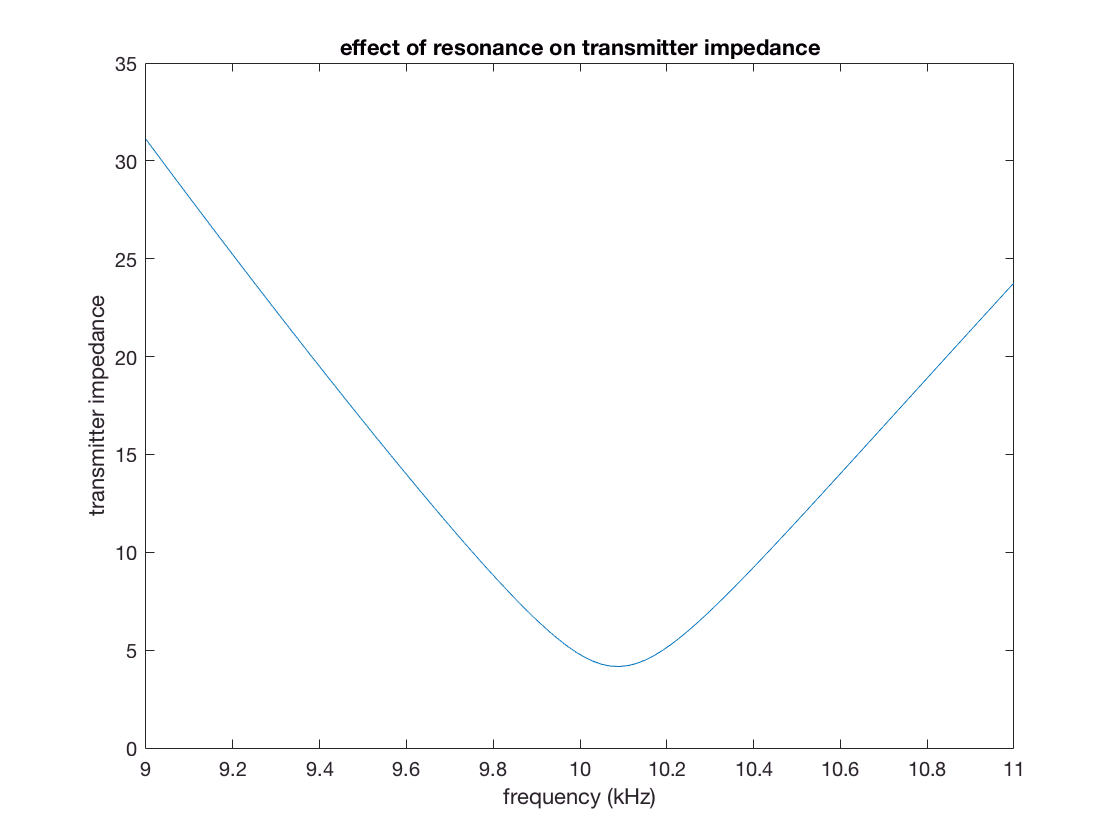

% calculate impedances
Z1 = TX_R + 1i*omega*TX_L + 1./(1i*omega*TX_C);
Z2 = RX_R + 1i*omega*RX_L + 1./(1i*omega*RX_C);
ZM = 1i*M'*omega;

% effect of resonance on transmitter & receiver impedances
figure(); plot(f*1e-3, abs(Z1)); title('effect of resonance on transmitter impedance');
    xlabel('frequency (kHz)'); ylabel('transmitter impedance');

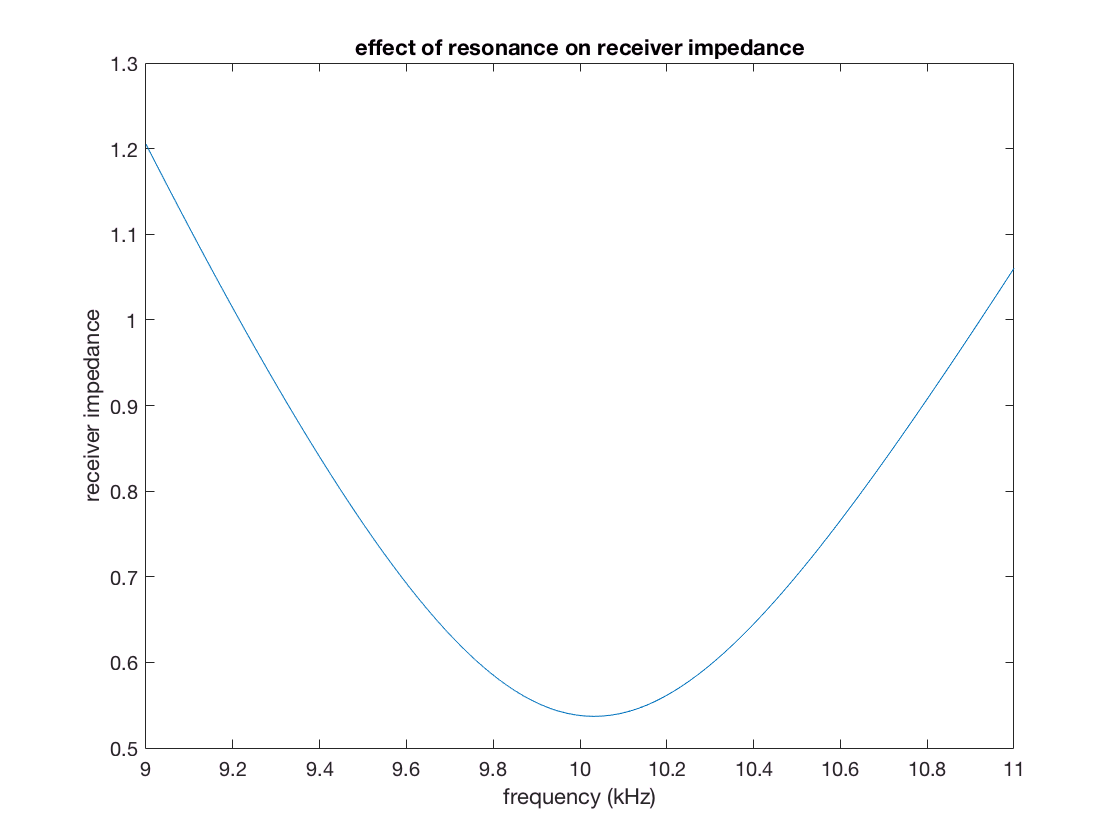

figure(); plot(f*1e-3, abs(Z2)); title('effect of resonance on receiver impedance');
    xlabel('frequency (kHz)'); ylabel('receiver impedance');

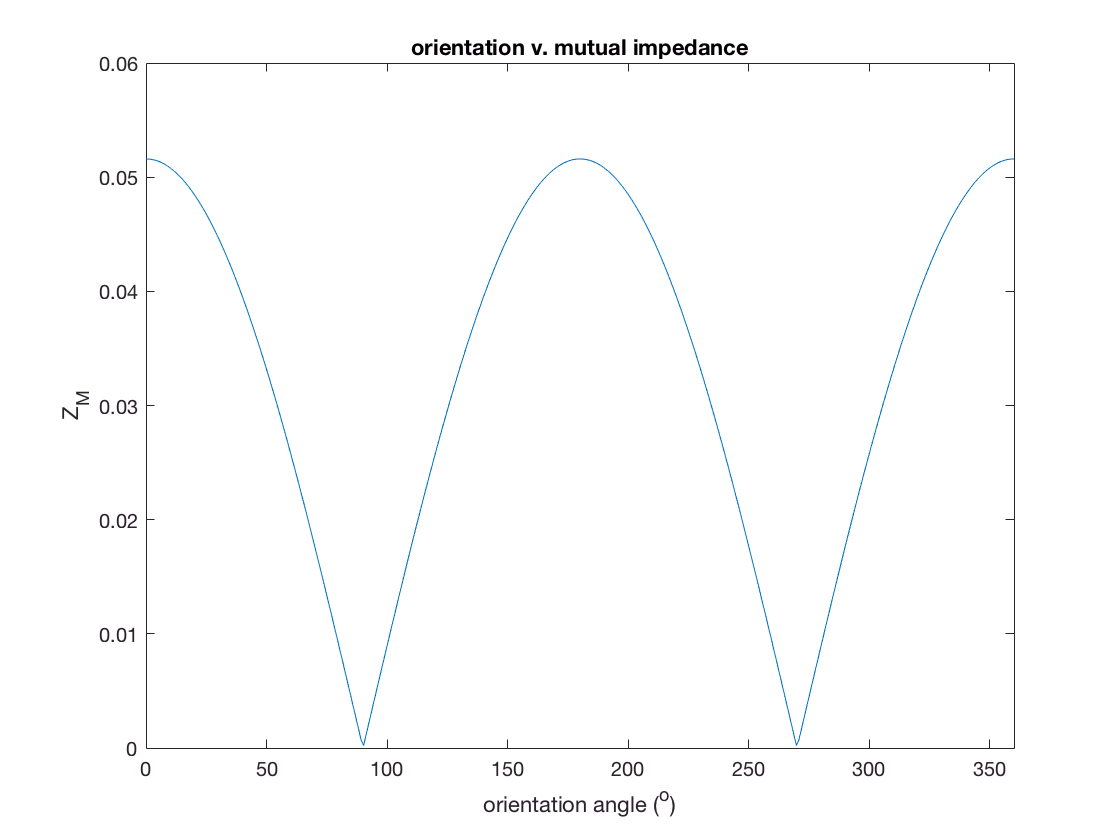


% effect of orientation of mutual impedance
figure(); plot(theta*180/pi, abs(ZM(:,55))); title('orientation v. mutual impedance');
    xlabel('orientation angle (^o)'); ylabel('Z_M'); xlim([0,360]);

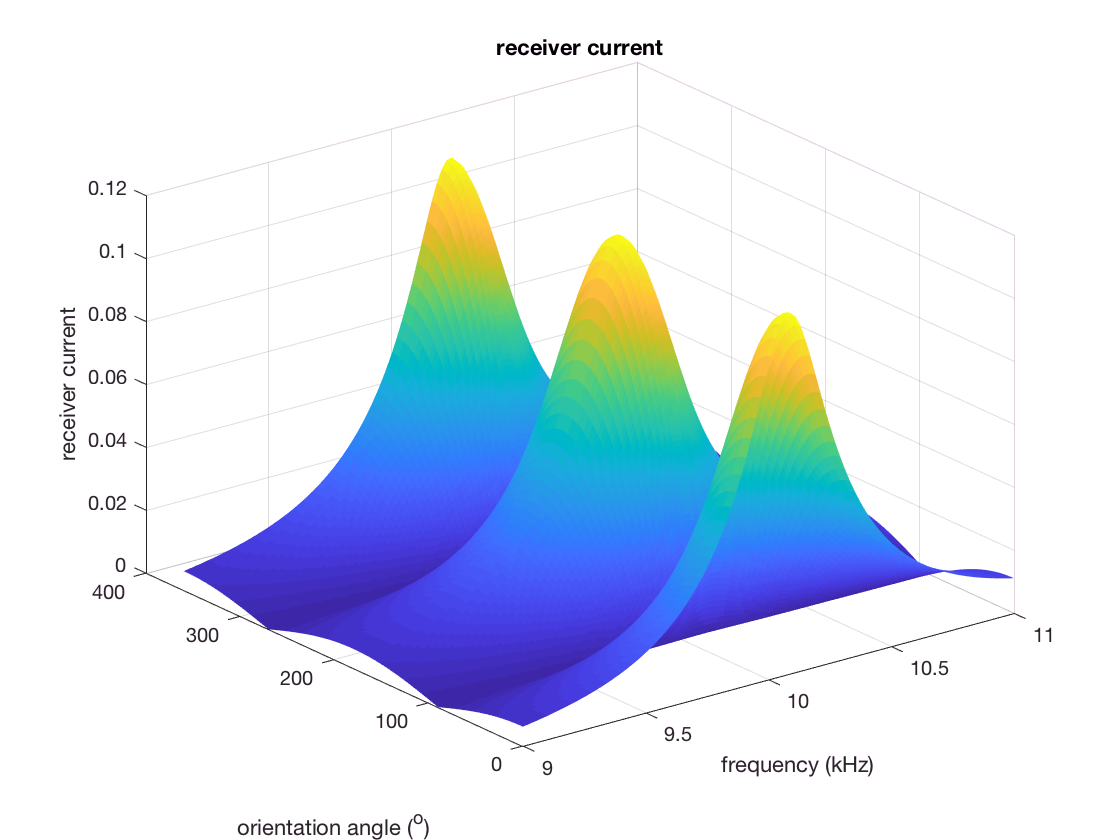


% calculate currents
I1 = TX_V*Z2 ./ (Z1.*Z2 - ZM.^2);
I2 = TX_V*ZM ./ (Z1.*Z2 - ZM.^2);

% receiver current visualisation
figure(); surf(f*1e-3, theta*180/pi, abs(I2), 'linestyle', 'none'); title('receiver current');
    xlabel('frequency (kHz)'); ylabel('orientation angle (^o)'); zlabel('receiver current');

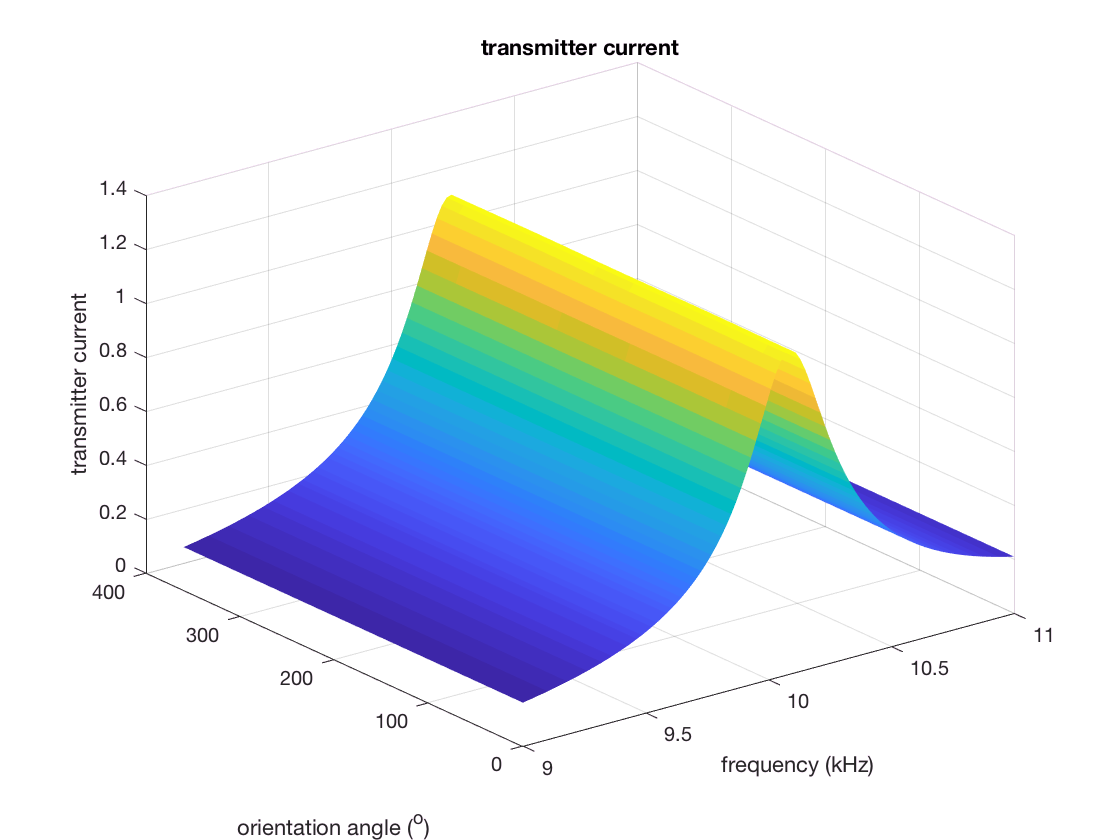


% transmitter current visualisation
figure(); surf(f*1e-3, theta*180/pi, abs(I1), 'linestyle', 'none'); title('transmitter current');
    xlabel('frequency (kHz)'); ylabel('orientation angle (^o)'); zlabel('transmitter current');

% effect of orientation on transmitter current
figure(); plot(theta*180/pi, I1(:,55)); title('effect of orientation on transmitter current');

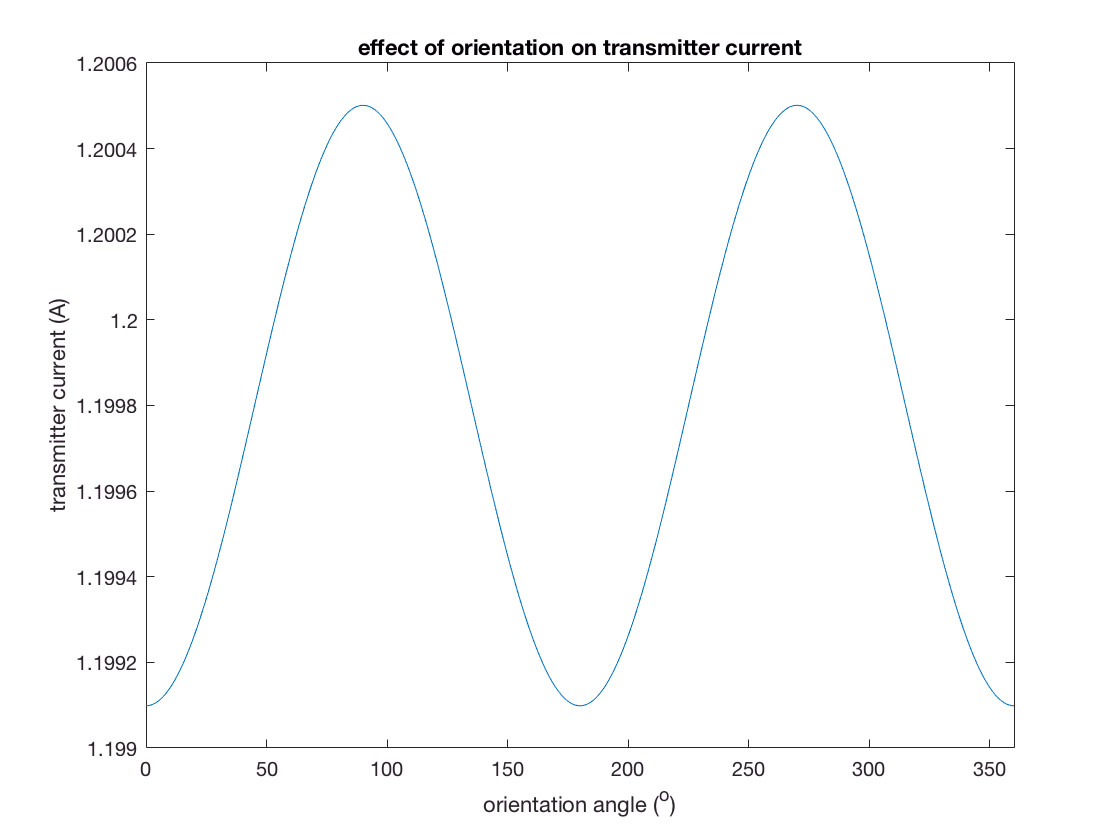

    xlabel('orientation angle (^o)'); ylabel('transmitter current (A)'); xlim([0,360]);

## Calculate V = I Z to check impedance calculations

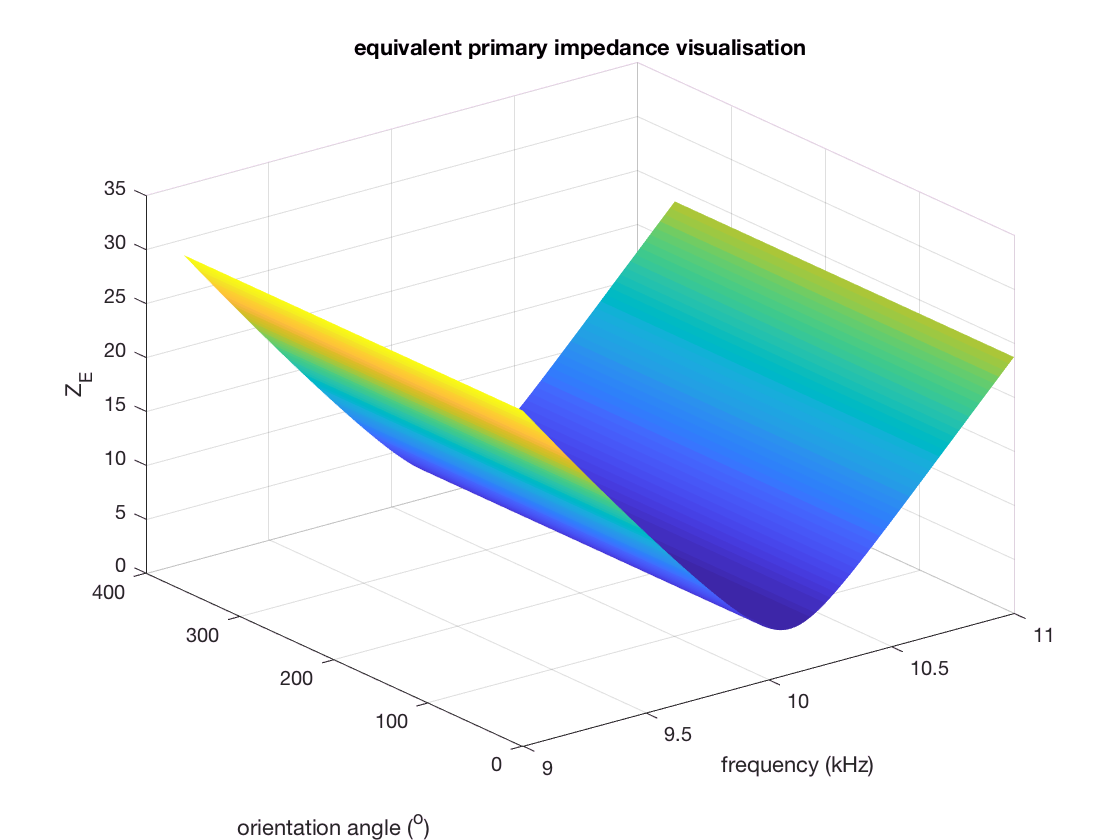

% equivalent primary impedance
ZE = Z1 - ZM.^2./Z2;
figure(); surf(f*1e-3, theta*180/pi, abs(ZE), 'linestyle', 'none');
    title('equivalent primary impedance visualisation');
    xlabel('frequency (kHz)'); ylabel('orientation angle (^o)'); zlabel('Z_E');

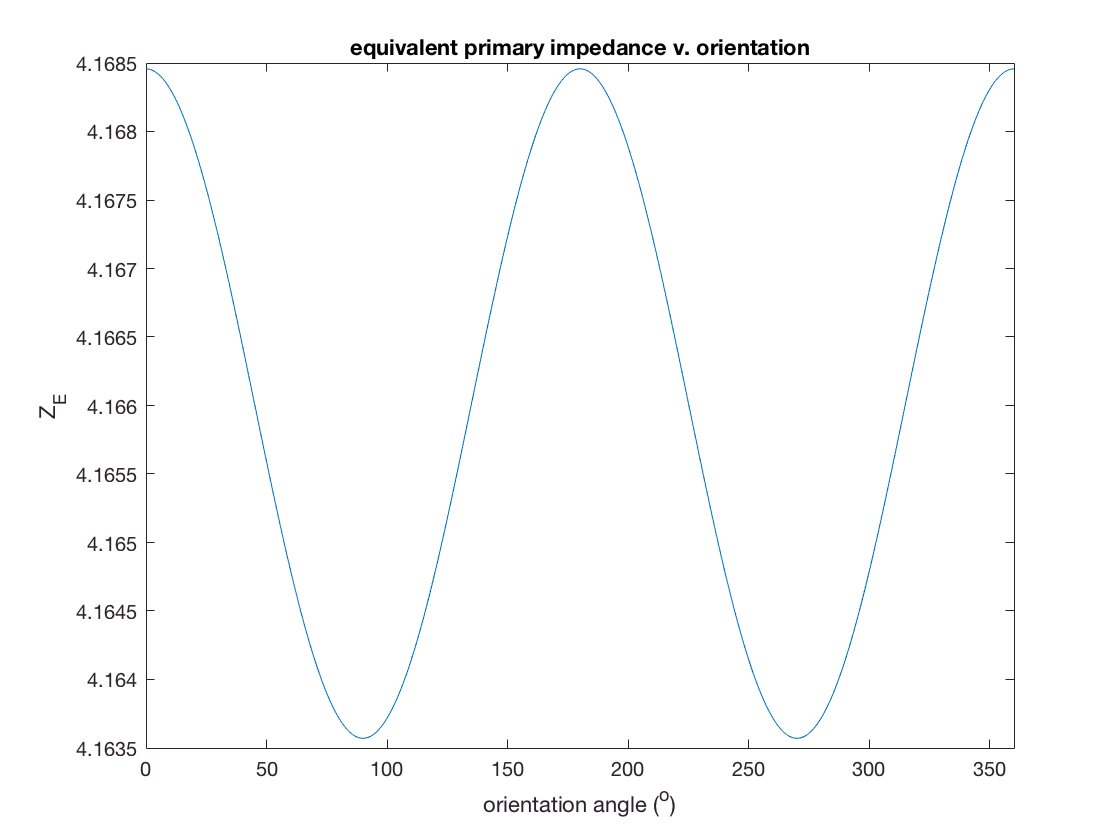

% highlight variation along orientation angle
figure(); plot(theta*180/pi, abs(ZE(:,55)));
    title('equivalent primary impedance v. orientation');
    xlabel('orientation angle (^o)'); ylabel('Z_E');
    xlim([0,360]);

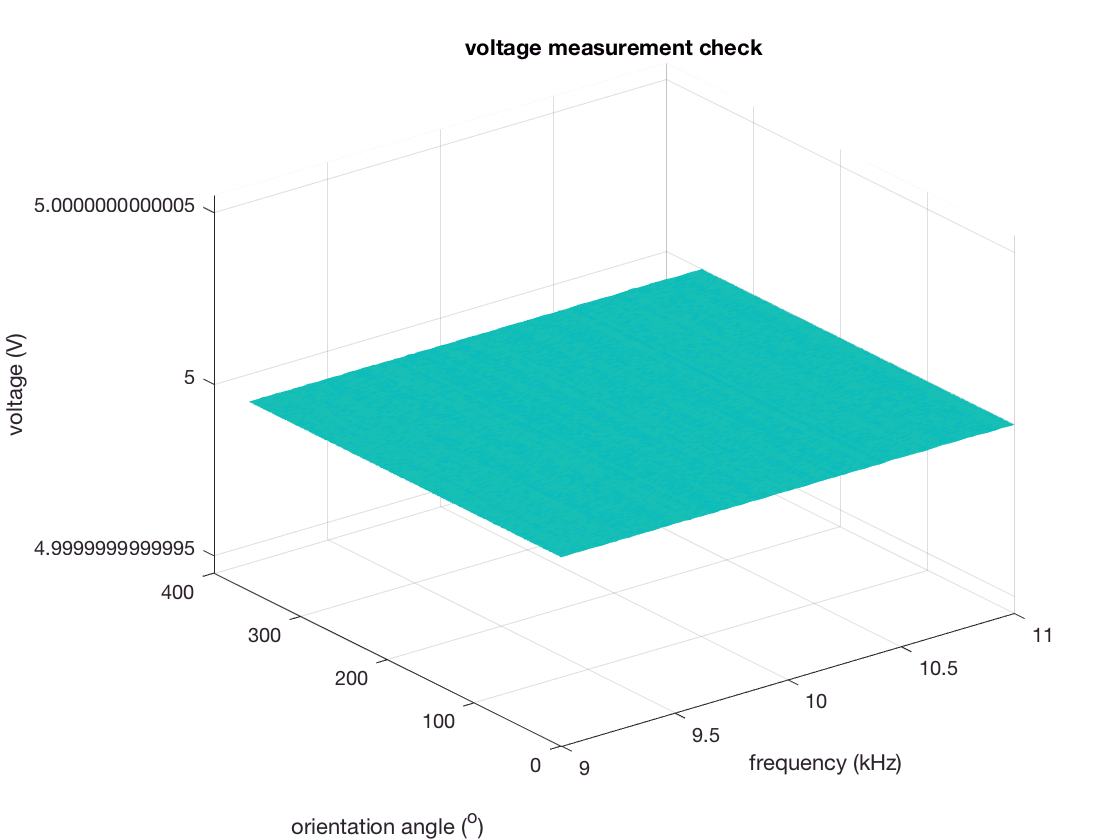


% equivalent impedance calculation check
V = I1 .* ZE;
figure(); surf(f*1e-3, theta*180/pi, abs(V), 'linestyle', 'none');
    title('voltage measurement check');
    xlabel('frequency (kHz)'); ylabel('orientation angle (^o)'); zlabel('voltage (V)');

## Measurement

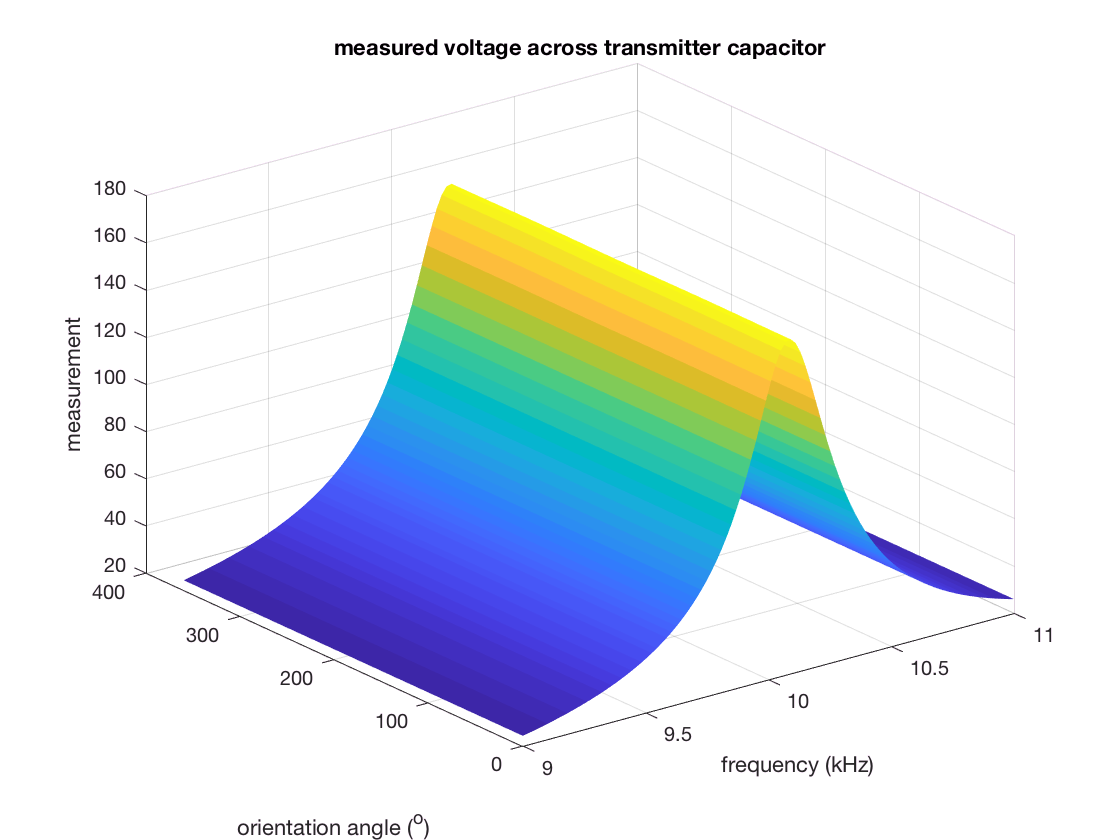

measurement = I1 .* (1 ./ (1i*omega*TX_C));
% measured voltage across transmitter capacitor
figure(); surf(f*1e-3, theta * 180/pi, abs(measurement), 'linestyle', 'none');
    title('measured voltage across transmitter capacitor');
    xlabel('frequency (kHz)'); ylabel('orientation angle (^o)'); zlabel('measurement');

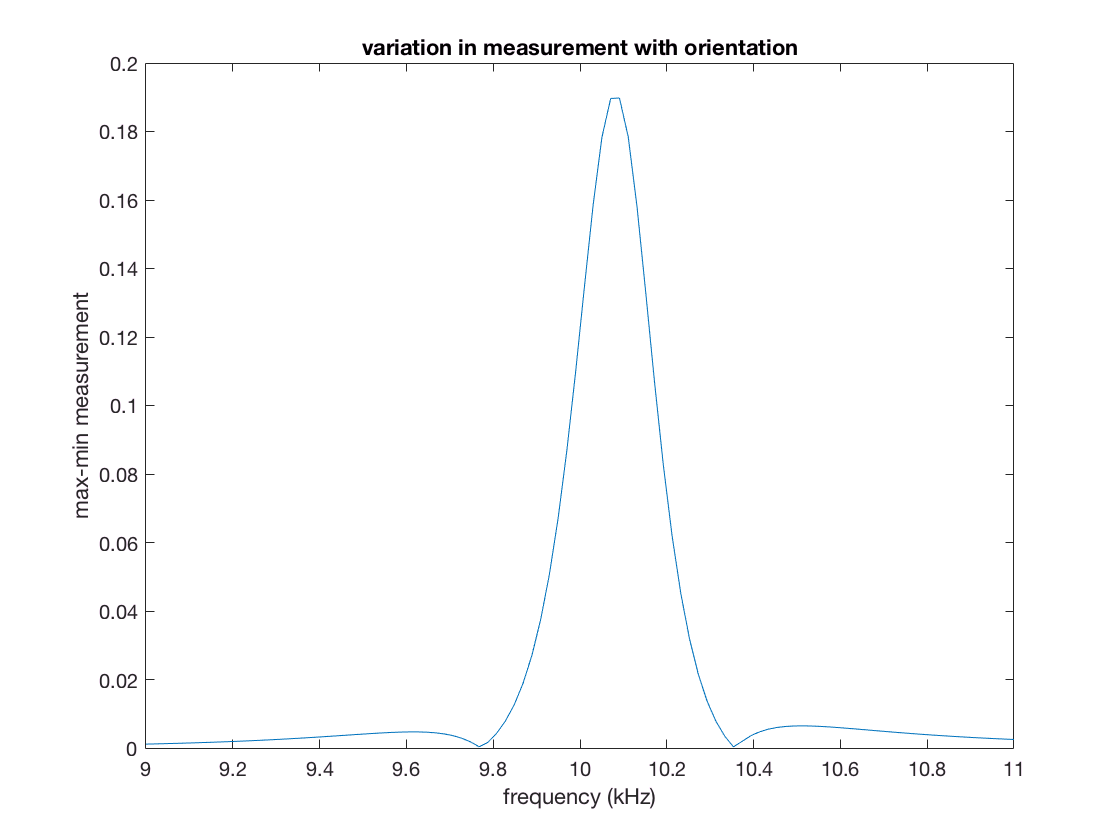


% variation with frequency & orientation
score = max(abs(measurement)) - min(abs(measurement));
figure(); plot(f*1e-3, score); title('variation in measurement with orientation');
    xlabel('frequency (kHz)'); ylabel('max-min measurement');

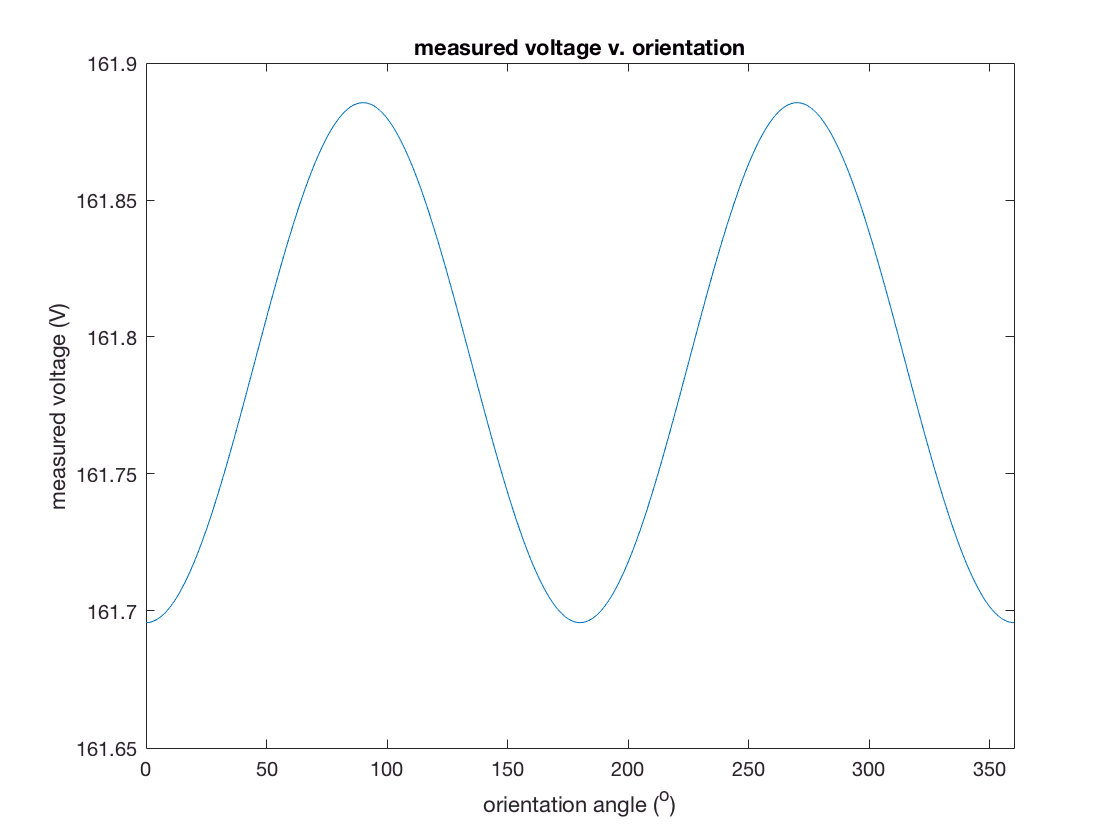

figure(); plot(theta*180/pi, abs(measurement(:,55)));
    title('measured voltage v. orientation');
    xlabel('orientation angle (^o)'); ylabel('measured voltage (V)');
    xlim([0,360]);